load flip_eqns.mat
load roll_eqns.mat


syms rw r2 r3 r5 l7_ab I7 m1 m2 m3 m4 m5 m6 m7 I1 I2 I3 I4 I5 I6 g2 C_friction7 ta13 a51 tv13 t13 T_z height1 length1 wheel_density frame_density gear_density gear_thickness frame_thickness wheel_thickness
design_parameters = [rw==0.075;
    r2==0.085/2;
    r3==0.055/2;
    r5==0.027/2;
    l7_ab==0.4;
    I7== 2;
    m7==0.5;
    C_friction7==0.1;
    gear_thickness==0.06;
    frame_thickness == 0.06;
    wheel_thickness == 0.06;
    gear_density== 1180; % kg/m^3 perspex
    frame_density== 1180; % kg/m^3 perspex
    wheel_density== 800; % kg/m^3 hardboard
    ];

derived_parameters = [
    length1==4*r5+4*r3+2*r2;
    height1==2*r2;
    m1==0.2*length1*height1*frame_thickness*frame_density;
    I1==m1/12*(length1.^2*height1.^2);
    m2==0.3*pi*r2.^2*gear_thickness*gear_density;
    m3==0.3*pi*r3.^2*gear_thickness*gear_density;
    m4==0.3*pi*r3.^2*gear_thickness*gear_density;
    m5==0.5*pi*r5.^2*gear_thickness*gear_density + 0.2*pi*rw.^2*wheel_thickness*wheel_density;
    m6==0.5*pi*r5.^2*gear_thickness*gear_density + 0.2*pi*rw.^2*wheel_thickness*wheel_density;
    I2==1/2*m2*r2.^2;
    I3==1/2*m3*r3.^2;
    I4==1/2*m4*r3.^2;
    I5==1/2*pi*r5.^4*gear_thickness*gear_density + 1/2*pi*rw.^4*wheel_thickness*wheel_density;
    I6==1/2*pi*r5.^4*gear_thickness*gear_density + 1/2*pi*rw.^4*wheel_thickness*wheel_density;
    g2==9.81;
    ];
derived_parameters = lhs(derived_parameters) == subs(rhs(derived_parameters), lhs(derived_parameters), rhs(derived_parameters));
derived_parameters = lhs(derived_parameters) == subs(rhs(derived_parameters), lhs(derived_parameters), rhs(derived_parameters));
derived_parameters = lhs(derived_parameters) == subs(rhs(derived_parameters), lhs(design_parameters), rhs(design_parameters));

solve([design_parameters; derived_parameters], [m1, m2, m3, m4, m5, m6, m7])

ans = struct with fields:
    m1: [0×1 sym]
    m2: [0×1 sym]
    m3: [0×1 sym]
    m4: [0×1 sym]
    m5: [0×1 sym]
    m6: [0×1 sym]
    m7: [0×1 sym]


double(rhs(derived_parameters))

ans =     0.2490
    0.0850
    0.2997
    0.0000
    0.1205
    0.0505
    0.0505
    0.1899
    0.1899
    0.0001



%apply to eqs

Q_eqn=subs(flip_eqns(1), lhs(derived_parameters), rhs(derived_parameters));
Q_eqn=subs(Q_eqn, lhs(design_parameters), rhs(design_parameters));
Q_eqn= ta13 == simplify(rhs(Q_eqn))


%R_eqn=subs(roll_eqns, lhs(design_parameters), rhs(design_parameters))
%R_eqn= lhs(R_eqn) == simplify(rhs(R_eqn))

testeqn= ta13 == simplify(rhs(subs(Q_eqn, [tv13], [0])))

testeqn= ta13 == simplify(rhs(subs(testeqn, [t13], [0])))

$$testeqn = {\mathrm{ta}}_{13}=-\frac{3500460247510278000000\,\pi -11460800000000000000000\,T_{z}+4251571150822200000\,\pi \,\sqrt{247}-315840000000000000000\,\sqrt{247}\,T_{z}+17764267101249600000\,\sqrt{247}+10053580156695504000000}{153\,\left(444419777709700000\,\pi +539781106530000\,\pi \,\sqrt{247}+904532925560961\,\sqrt{247}+18267932108711857890\right)}$$


%testeqn2= ta13 == rhs(subs(R_eqn(1), [tv13], [0]))
%testeqn2= ta13 == rhs(subs(testeqn2, [t13], [0]))
%testeqn2= ta13 == simplify(rhs(testeqn2))

%create plot of required torque vs position
P_eqn=subs(Q_eqn, [tv13, ta13], [0, 0])

P_eqn=isolate(P_eqn, T_z)

$$P\_eqn = \begin{array}{l} T_{z}=\frac{\frac{410798676716397\,\sin\left(2\,t_{13}\right)\,\sigma_{2}}{40}+\frac{55513334691405\,\cos\left(t_{13}\right)\,\sigma_{1}}{4}+\frac{2543922104427\,\cos\left(t_{13}\right)\,\sigma_{3}}{2}+57848343750\,\sin\left(t_{13}\right)\,\sigma_{3}+\frac{106289278770555\,\pi \,\cos\left(t_{13}\right)\,\sigma_{1}}{32}+\frac{7085951918037\,\pi \,\cos\left(t_{13}\right)\,\sigma_{3}}{16}+\frac{786540662902107\,\pi \,\sin\left(2\,t_{13}\right)\,\sigma_{2}}{320}}{1450000000000\,\sigma_{3}+10875000000000\,\sigma_{2}+235875000000000\,\cos\left(t_{13}\right)\,\sigma_{1}-7492500000000\,\sin\left(t_{13}\right)\,\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}={\left(12321\,{\cos\left(t_{13}\right)}^{2}-16650\,\sin\left(t_{13}\right)+142054\right)}^{3/2}\\ \sigma_{2}={\left(-\sigma_{4}-16650\,\sin\left(t_{13}\right)+154375\right)}^{3/2}\\ \sigma_{3}={\left(\sigma_{4}+16650\,\sin\left(t_{13}\right)-154375\right)}^{2}\\ \sigma_{4}=12321\,{\sin\left(t_{13}\right)}^{2} \end{array}$$

xvals=linspace(0, pi/2, 100)

xvals =          0    0.0159    0.0317    0.0476    0.0635    0.0793    0.0952    0.1111    0.1269    0.1428    0.1587    0.1745    0.1904    0.2063    0.2221    0.2380    0.2539    0.2697    0.2856    0.3015    0.3173    0.3332    0.3491    0.3649    0.3808    0.3967    0.4125    0.4284    0.4443    0.4601    0.4760    0.4919    0.5077    0.5236    0.5395    0.5553    0.5712    0.5871    0.6029    0.6188    0.6347    0.6505    0.6664    0.6823    0.6981    0.7140    0.7299    0.7457    0.7616    0.7775


yvals = linspace(0, 0, 100)

yvals =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


syms Tf(t13)
Tf(t13) = rhs(P_eqn)

$$Tf(t13) = \begin{array}{l} \frac{\frac{410798676716397\,\sin\left(2\,t_{13}\right)\,\sigma_{2}}{40}+\frac{55513334691405\,\cos\left(t_{13}\right)\,\sigma_{1}}{4}+\frac{2543922104427\,\cos\left(t_{13}\right)\,\sigma_{3}}{2}+57848343750\,\sin\left(t_{13}\right)\,\sigma_{3}+\frac{106289278770555\,\pi \,\cos\left(t_{13}\right)\,\sigma_{1}}{32}+\frac{7085951918037\,\pi \,\cos\left(t_{13}\right)\,\sigma_{3}}{16}+\frac{786540662902107\,\pi \,\sin\left(2\,t_{13}\right)\,\sigma_{2}}{320}}{1450000000000\,\sigma_{3}+10875000000000\,\sigma_{2}+235875000000000\,\cos\left(t_{13}\right)\,\sigma_{1}-7492500000000\,\sin\left(t_{13}\right)\,\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}={\left(12321\,{\cos\left(t_{13}\right)}^{2}-16650\,\sin\left(t_{13}\right)+142054\right)}^{3/2}\\ \sigma_{2}={\left(-\sigma_{4}-16650\,\sin\left(t_{13}\right)+154375\right)}^{3/2}\\ \sigma_{3}={\left(\sigma_{4}+16650\,\sin\left(t_{13}\right)-154375\right)}^{2}\\ \sigma_{4}=12321\,{\sin\left(t_{13}\right)}^{2} \end{array}$$

%fplot(Tf(t13), [0, pi/2])

%for i = 1:100
%    yvals=rhs(subs(P_eqn, t13, xvals(i)))
%end
%plot(xvals, yvals)

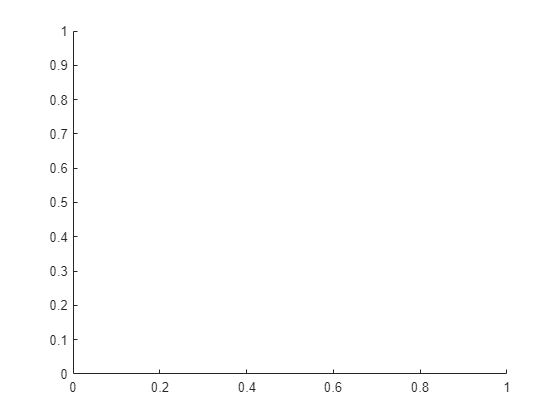


hold off


xvals=zeros(length(design_parameters),100)

xvals =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

yvals=zeros(length(design_parameters),100)

yvals =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

yvals2=zeros(length(design_parameters),100)

yvals2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

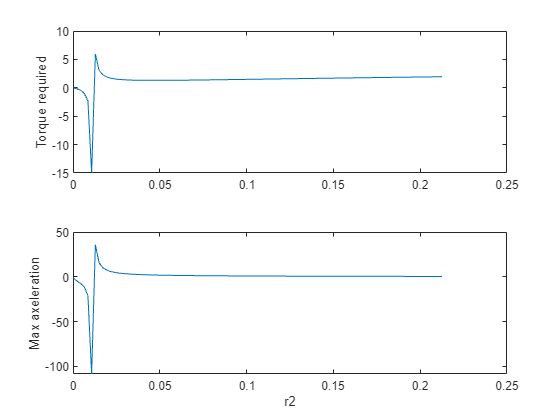

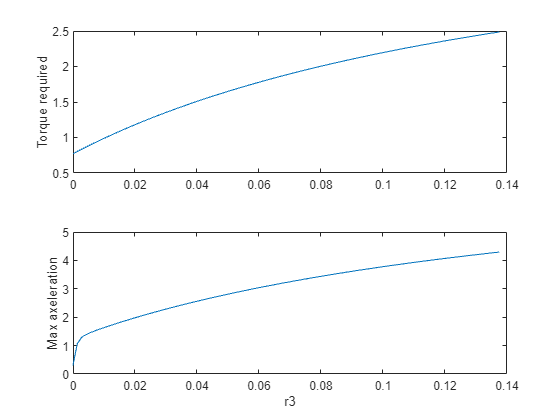

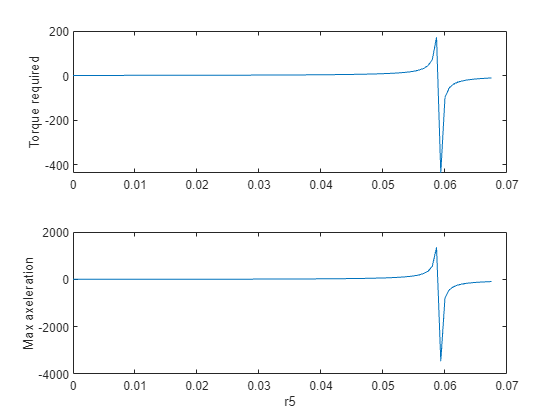

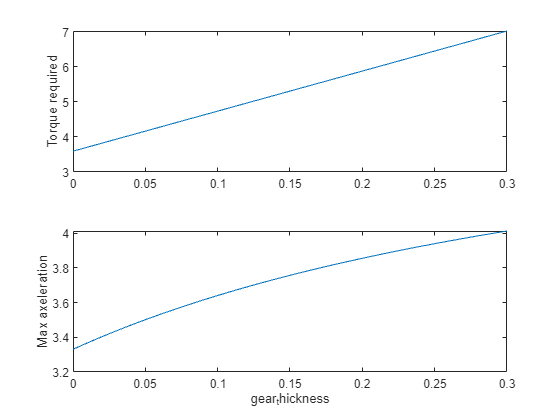

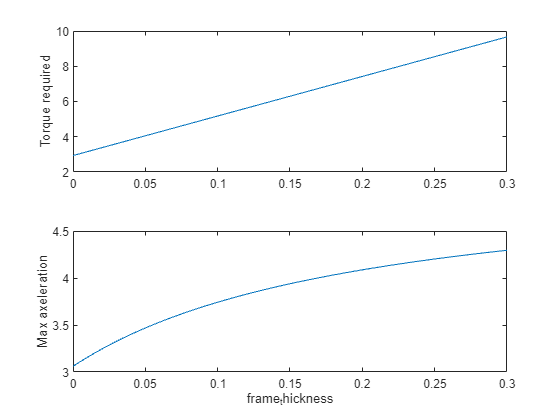

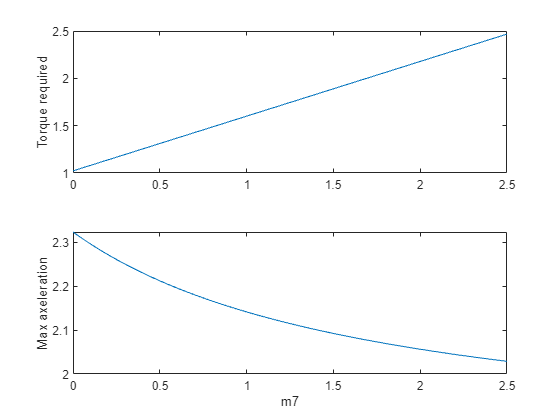

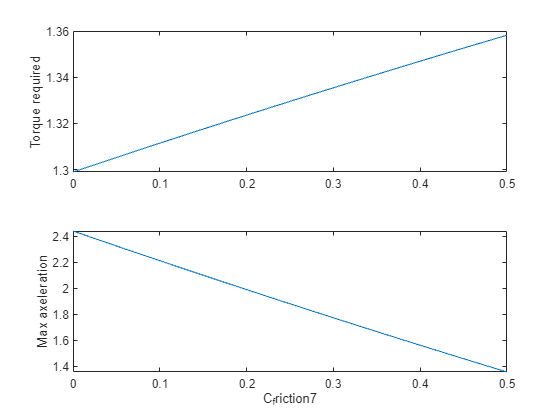

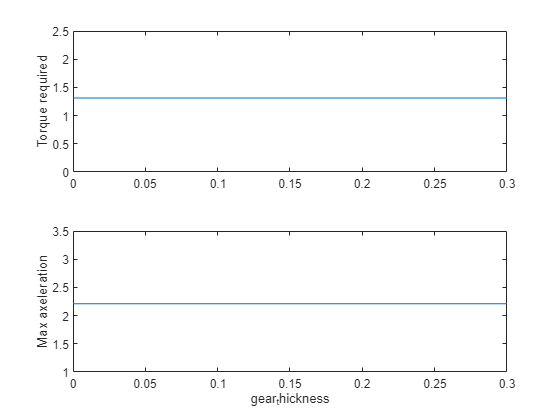


Q_eqn=subs(flip_eqns(1), lhs(derived_parameters), rhs(derived_parameters));
R_eqn=subs(roll_eqns(2), lhs(derived_parameters), rhs(derived_parameters));

for i=1:length(design_parameters)
    P_eqn=subs(Q_eqn, lhs(design_parameters(1:end ~=i)), rhs(design_parameters(1:end ~=i)));
    P_eqn=subs(P_eqn, [tv13, ta13, t13], [0, 0, 0]);
    P_eqn=isolate(P_eqn, T_z);
    xvals(i,:)=linspace(1e-10, 5*rhs(design_parameters(i)), 100);

    for k = 1:100
        try
            yvals(i,k)=real(double(rhs(subs(P_eqn, lhs(design_parameters(i)), xvals(i,k)))));
        catch 
        end
    end

    P_eqn=subs(R_eqn, lhs(design_parameters(1:end ~=i)), rhs(design_parameters(1:end ~=i)));
    P_eqn=subs(P_eqn, [tv13, ta13, t13], [0, 0, 0]);
    %P_eqn=isolate(P_eqn, T_z);
    for k = 1:100
        try
            yvals2(i,k)=real(double(rhs(subs(P_eqn, [lhs(design_parameters(i)),T_z], [xvals(i,k), yvals(i,k)]))));
        catch 
        end
    end
    figure
    hold on
    tiledlayout(2,1)
    nexttile
    plot(xvals(i,:), yvals(i,:))
    ylabel("Torque required")
    nexttile
    plot(xvals(i,:), yvals2(i,:))
    ylabel("Max axeleration")
    xlabel(string(lhs(design_parameters(i))))
    hold off
end    